%% Slotted ALOHA仿真
clc
clear
% 设置系统参数
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
N = 50;%用户数
lambdas = [linspace(0.000010,20,N/2) linspace(20,80,N/2)];%单个用户的帧到达率集合（是一个复数）
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
b = 100;
R = 1e5;
T_fr = b/R;
T = 1e2;%总仿真随机接入时长，可以根据仿真情况适当修改

lambdalength = length(lambdas);
rho_simu1 = zeros(size(lambdas));
rho_simu2 = zeros(size(lambdas));%设置某一用户在发送帧的过程中不会有新的帧到达该用户时计算的归一化吞吐速率
tic
for lambdaCounter = 1:lambdalength
    lambda = lambdas(lambdaCounter);
    % 生成所有用户的帧到达时刻-TotalFrameArrivalTimes
    MAX_number_of_arrived_frames_in_T_for_each_user=ceil(T*lambda + 5*sqrt(T*lambda));
    %这两个数组对应的是仿真时间内可以有的时隙数目
    slots1=zeros(1,ceil(T/T_fr));
    slots2=zeros(1,ceil(T/T_fr));
    %N个用户
    for n = 1:N
        FrameArrivalTimes=zeros(1,MAX_number_of_arrived_frames_in_T_for_each_user);
        number_of_arrived_frames=0;
        FrameArrivalTime = -1/lambda*log(rand);
        while FrameArrivalTime<T
            %按照指数分布的方式生成帧到达时间
            number_of_arrived_frames=number_of_arrived_frames+1;
            FrameArrivalTimes(number_of_arrived_frames) = FrameArrivalTime;
            FrameArrivalTime=FrameArrivalTime+(-1/lambda)*log(rand);
        end%结束后就根据上面的随机时间生成了所有可能的尝试arrival时间
        
        %将每个包在对应时间的slot发送，并记录该slot的使用情况
        for i=1:number_of_arrived_frames
            slot_index=ceil(FrameArrivalTimes(i)/T_fr);%根据arrivaltime确定在哪个时隙发送
            slots1(slot_index)=slots1(slot_index)+1;%每个slot可能有多个发送占用
        end

        FrameArrivalTimes=zeros(1,MAX_number_of_arrived_frames_in_T_for_each_user);
        number_of_arrived_frames=0;
        FrameArrivalTime = -1/lambda*log(rand);
        while FrameArrivalTime<T
            %设置一个用户不会和自己的帧产生冲突
            number_of_arrived_frames=number_of_arrived_frames+1;
            FrameArrivalTimes(number_of_arrived_frames) = FrameArrivalTime;
            FrameArrivalTime=FrameArrivalTime+T_fr+(-1/lambda)*log(rand);%设置2的时间间隔不同
        end
        for i=1:number_of_arrived_frames
            slot_index=ceil(FrameArrivalTimes(i)/T_fr);
            slots2(slot_index)=slots2(slot_index)+1;
        end
    end

    % 统计仿真时长T内总的成功发送的帧的数量并计算归一化吞吐速率 
    rho_simu1(lambdaCounter) = sum(slots1==1)/T*T_fr; %若某个slot只有一个包被发送则传输成功，反之传输失败
    rho_simu2(lambdaCounter) = sum(slots2==1)/T*T_fr;
end
toc

历时 0.805813 秒。


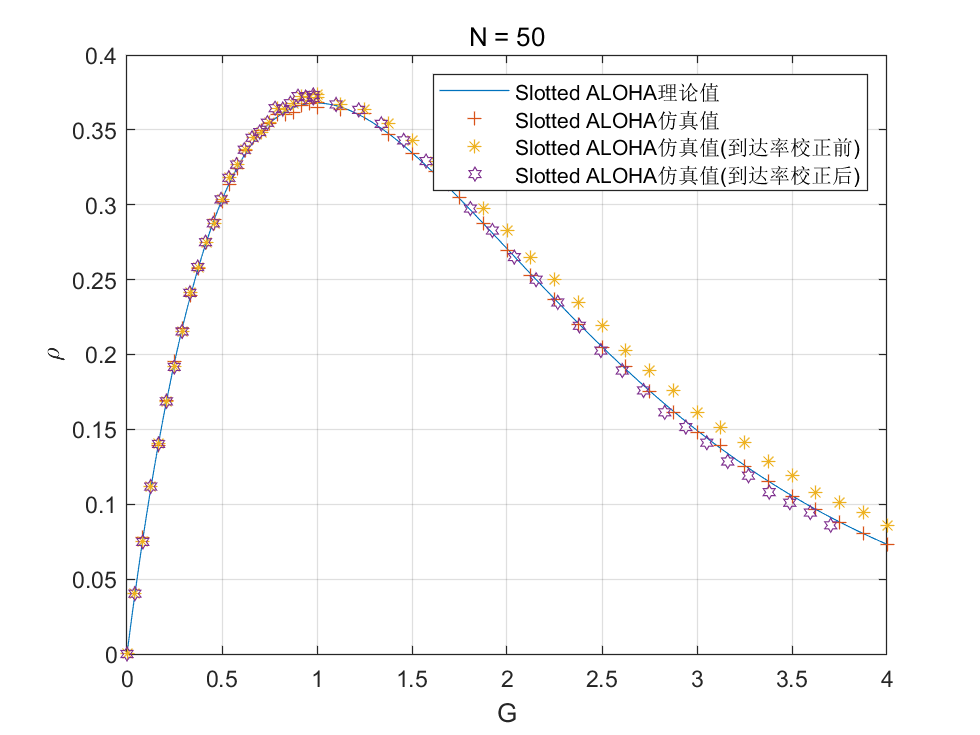


figure
G_s = 0:0.01:N*lambdas(end)*T_fr;
plot(G_s,G_s.*exp(-G_s),'DisplayName','Slotted ALOHA理论值')
hold on
plot(N*lambdas*T_fr,rho_simu1,'+','DisplayName','Slotted ALOHA仿真值')
hold on
plot(N*lambdas*T_fr,rho_simu2,'*','DisplayName','Slotted ALOHA仿真值(到达率校正前)')
hold on
plot(N*(lambdas./(1+lambdas*T_fr))*T_fr,rho_simu2,'hexagram','DisplayName','Slotted ALOHA仿真值(到达率校正后)')
legend
grid on
title(['N = ', num2str(N)])
xlabel('G')
ylabel('\rho')